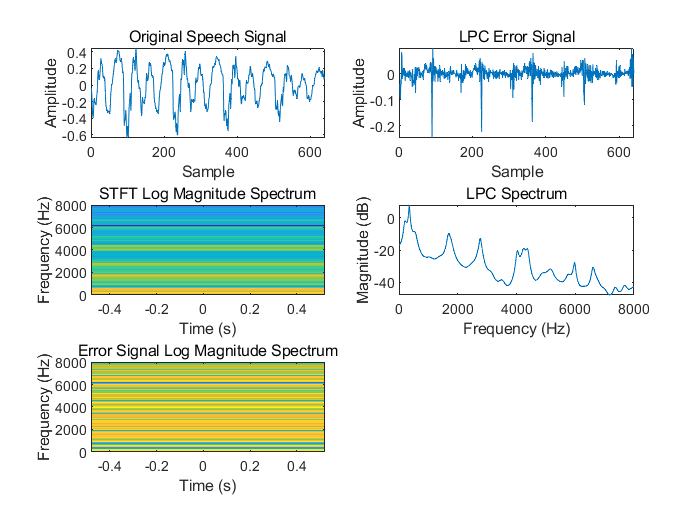

% Load speech signal
[speech,fs] = audioread('test_16k.wav');

% Define frame length and overlap
frame_length = 0.03; % 30 ms
overlap = 0.5; % 50%

% Convert frame length and overlap to samples
frame_length_samples = 640;
overlap_samples = round(overlap*frame_length_samples);

% Define start and end samples of frame
start_sample = 6000;
end_sample = start_sample + frame_length_samples - 1;

% Extract frame of speech
speech_frame = speech(start_sample:end_sample);

% Perform LPC analysis on frame
p = 64; % LPC order
[a,g] = lpc(speech_frame,p);

% Generate LPC error signal
lpc_error = filter(a,1,speech_frame);

% Compute short-time Fourier transform log magnitude spectrum (dB)
window = hamming(frame_length_samples);
nfft = 2^nextpow2(frame_length_samples);
[S,F0,T1] = spectrogram(speech_frame,window,overlap_samples,nfft,fs);
S_log_mag = 20*log10(abs(S));

% Compute LPC spectrum
[H,F1] = freqz(sqrt(g),a,nfft,fs);
H_log_mag = 20*log10(abs(H));

% Compute error signal log magnitude spectrum
[E,F2,T2] = spectrogram(lpc_error,window,overlap_samples,nfft,fs);
E_log_mag = 20*log10(abs(E));

% Plot all quantities on a single page
figure;
subplot(3,2,1);
plot(speech_frame);
title('Original Speech Signal');
xlabel('Sample');
ylabel('Amplitude');
subplot(3,2,2);
plot(lpc_error);
title('LPC Error Signal');
xlabel('Sample');
ylabel('Amplitude');
subplot(3,2,3);
imagesc(T1,F0,S_log_mag);
axis xy;
title('STFT Log Magnitude Spectrum');
xlabel('Time (s)');
ylabel('Frequency (Hz)');
subplot(3,2,4);
plot(F1,H_log_mag);
title('LPC Spectrum');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');
subplot(3,2,5);
imagesc(T2,F2,E_log_mag);
axis xy;
title('Error Signal Log Magnitude Spectrum');
xlabel('Time (s)');
ylabel('Frequency (Hz)');